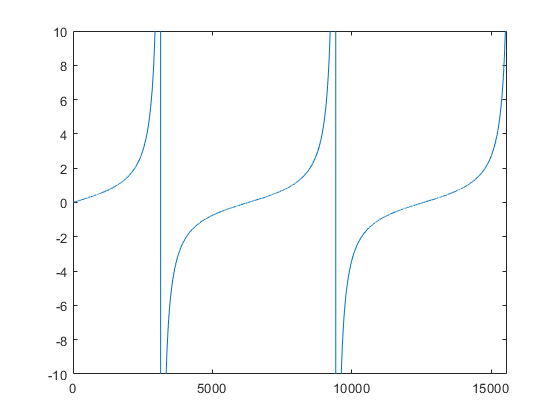

nf = 1.50;
ns = 1.45;
nc = 1.40;
h = 0.0005;
lambda = 1.55*10^(-4);
k = 2*pi/lambda;

kappamax = sqrt(k^2*nf^2-k^2*ns^2);
kappa= 0:1:kappamax;
beta = sqrt(k^2*nf^2-kappa.^2);

gammas=sqrt(beta.^2-k^2*ns^2);
gammac=sqrt(beta.^2-k^2*nc^2);

plot(kappa,tan(kappa.*h))
hold on
plot(kappa,(gammas+gammac)/(kappa.*(1-gammas.*gammac/kappa.^2)))
axis([0 kappamax -10 10])